# Assignment 2

## initialize

close all;
clc

## 1. parameters

the parameter of the car is shown as below:

% physical params
g = 9.8;

% vehicle params
weight = 1807.2; % kg
wheelbase = 2950*10^-3; % mm->m
R_tire = 402*10^-3; % mm->m
beta_1 = 3.538;
beta_2 = 2.06;
beta_3 = 1.404;
beta_4 = 1;
beta_5 = 0.713;
beta_6 = 0.582;
beta_dif = 4.1;

% engine params
speed_max = 6200; % rpm
speed_min = 725; % rpm
omega_max = speed_max*0.1047198; % rpm->rad/s
omega_min = speed_min*0.1047198; % rpm->rad/s, idle

yita_d = 1; % differencial efficiency
yita_g = 1; % gear box efficiency

% resistance params
%%%%%%%%%%%%%%%%%%%%% it hasn't been done yet%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
mu_R = 0.02;
gradient_degree = 59.7;
gradient = deg2rad(gradient_degree);
A = 3; % m^2
rho = 1.29;
c_d = 0.3; % drag coefficient

% simulation params
dt = 0.01; % s

## 2.torque engine speed

### the origional torque-engine speed map

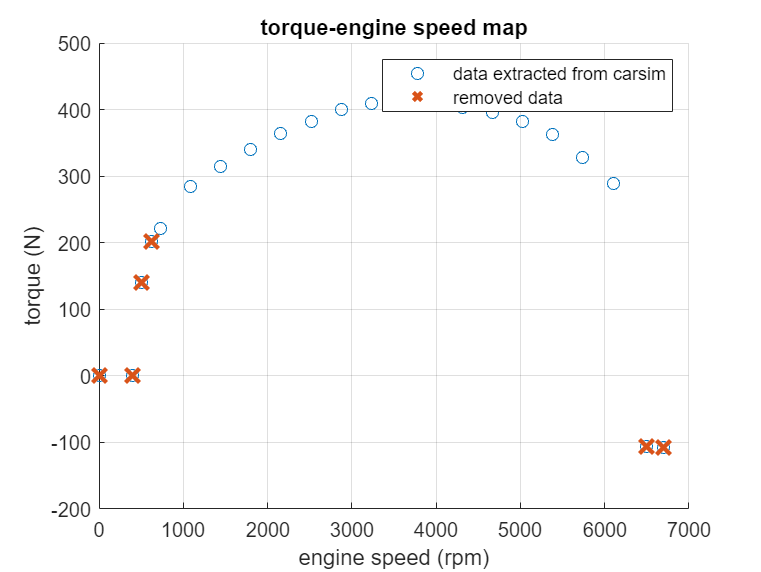

% the data is extracted from the carsim
engine_speed_torque_table = readtable('torque_engine_speed.csv');
all_map_engine_spped = engine_speed_torque_table{2:end,1}';
all_map_torque = engine_speed_torque_table{2:end,end}';

unused_x = all_map_engine_spped(all_map_engine_spped<speed_min | all_map_engine_spped>speed_max);
unused_y = all_map_torque(all_map_engine_spped<speed_min | all_map_engine_spped>speed_max);

% plot
scatter(all_map_engine_spped,all_map_torque);
hold on;
scatter(unused_x,unused_y, 100, 'x','LineWidth',2);

title("torque-engine speed map");
legend('data extracted from carsim','removed data');
xlabel("engine speed (rpm)");
ylabel("torque (N)");
grid on;
hold off

### map

In order to have the best approximation of the state of the vehicle, I remove some values, the new plot is shown as below.

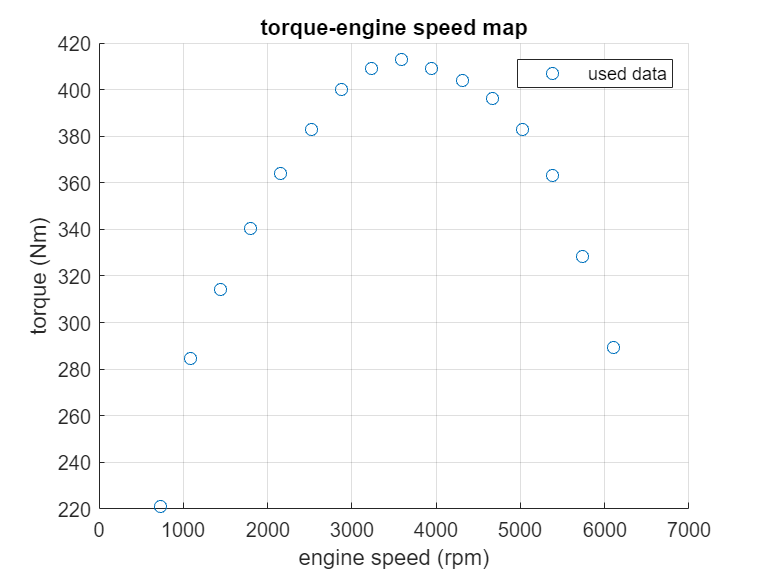

% the data is extracted from the carsim
map_engine_spped = all_map_engine_spped(all_map_engine_spped >= speed_min & all_map_engine_spped <= speed_max);
map_torque = all_map_torque(all_map_engine_spped >= speed_min & all_map_engine_spped <= speed_max);

% plot
scatter(map_engine_spped,map_torque);

title("torque-engine speed map");
legend('used data')
xlabel("engine speed (rpm)");
ylabel("torque (Nm)");
grid on;

### poly fit

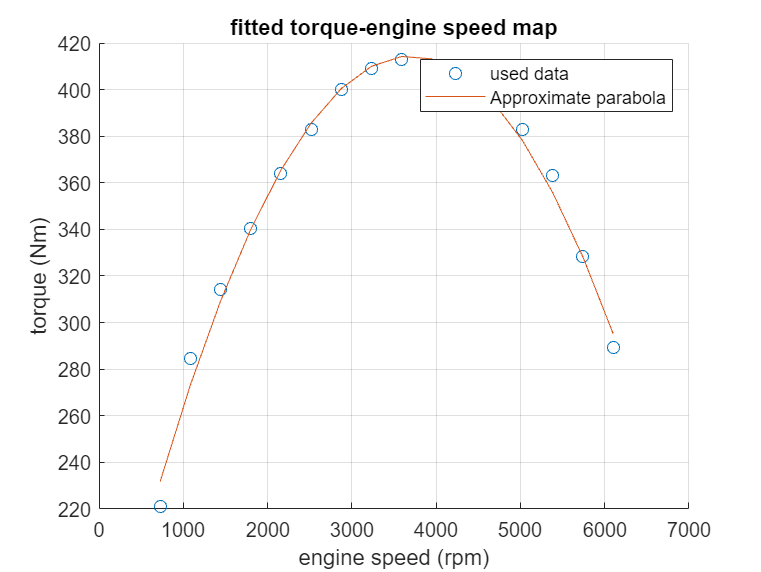

[p,ErrorEst] = polyfit(map_engine_spped,map_torque,2);
pop_fit = polyval(p,map_engine_spped,ErrorEst);
hold on;

% plot
plot(map_engine_spped,pop_fit)
title("fitted torque-engine speed map");
legend('used data','Approximate parabola');
hold off;

## 3.Torque Engine Speed Map with Different Gear Box

This is Torque (Nm) vs. Wheel Speed (rpm)

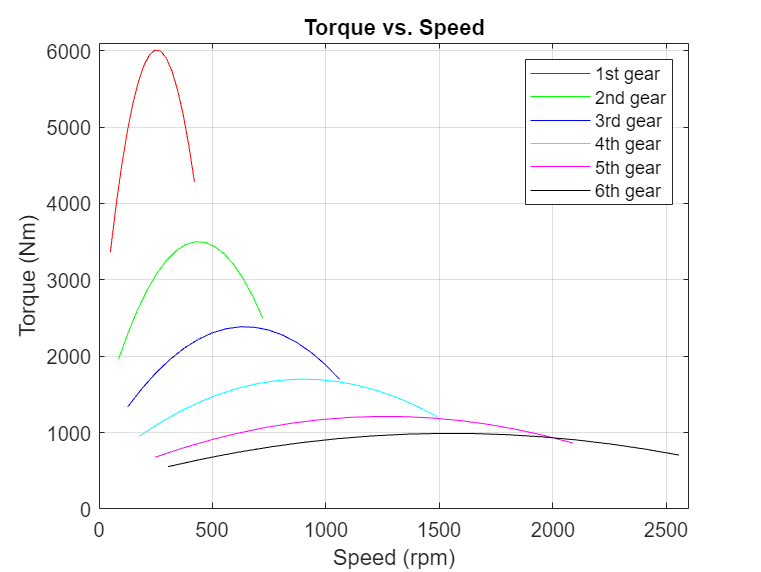

% calculate the torque of each gear
x1 = map_engine_spped / beta_dif / beta_1;
y1 = beta_dif * beta_1 * polyval(p, map_engine_spped, ErrorEst);
x2 = map_engine_spped / beta_dif / beta_2;
y2 = beta_dif * beta_2 * polyval(p, map_engine_spped, ErrorEst);
x3 = map_engine_spped / beta_dif / beta_3;
y3 = beta_dif * beta_3 * polyval(p, map_engine_spped, ErrorEst);
x4 = map_engine_spped / beta_dif / beta_4;
y4 = beta_dif * beta_4 * polyval(p, map_engine_spped, ErrorEst);
x5 = map_engine_spped / beta_dif / beta_5;
y5 = beta_dif * beta_5 * polyval(p, map_engine_spped, ErrorEst);
x6 = map_engine_spped / beta_dif / beta_6;
y6 = beta_dif * beta_6  * polyval(p, map_engine_spped, ErrorEst);

plot(x1, y1, 'r', x2, y2, 'g', x3, y3, 'b', x4, y4, 'c', x5, y5, 'm', x6, y6, 'k');
legend('1st gear', '2nd gear', '3rd gear', '4th gear', '5th gear', '6th gear');
title('Torque vs. Speed');
xlabel('Speed (rpm)');
ylabel('Torque (Nm)');
xlim([0 2600])
ylim([0 6100])
grid on;

## 4.Traction Force vs Vehicle Speed

Traction Force (N) vs Vehicle Speed (m/s)

hold off;

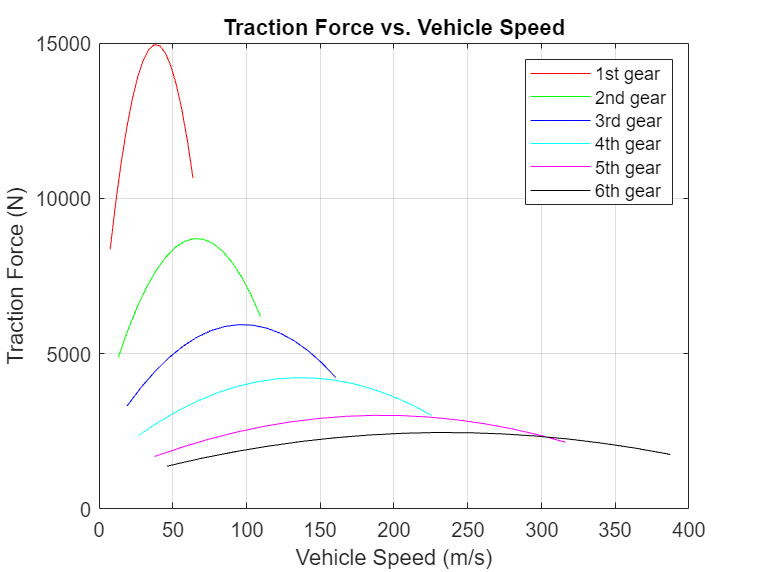

% convert the Wheel torque to Traction Force
y11 = y1/R_tire;
y12 = y2/R_tire;
y13 = y3/R_tire;
y14 = y4/R_tire;
y15 = y5/R_tire;
y16 = y6/R_tire;

x11 = x1 * R_tire * 2 * pi / 60 * 3.6; % convert to kph
x12 = x2 * R_tire * 2 * pi / 60 * 3.6; % convert to kph
x13 = x3 * R_tire * 2 * pi / 60 * 3.6; % convert to kph
x14 = x4 * R_tire * 2 * pi / 60 * 3.6; % convert to kph
x15 = x5 * R_tire * 2 * pi / 60 * 3.6; % convert to kph
x16 = x6 * R_tire * 2 * pi / 60 * 3.6; % convert to kph

plot(x11, y11, 'r', x12, y12, 'g', x13, y13, 'b', x14, y14, 'c', x15, y15, 'm', x16, y16, 'k');
legend('1st gear', '2nd gear', '3rd gear', '4th gear', '5th gear', '6th gear');
title('Traction Force vs. Vehicle Speed');
xlabel('Vehicle Speed (m/s)');
ylabel('Traction Force (N)');
grid on;

### Resistant Force with different gear box sets

#### resistance formulation

According to the slide, the resistance formulation is shown below:


$$F_{R}=wsin\alpha_{road}+\mu_{R}w+\frac{1}{2}\rho c_{d}Au^{2}$$


$w = mg$, $B_0 = w \sin{\alpha_{road}} + \mu_R w$, $B_1=\frac{1}{2}\rho c_d A$

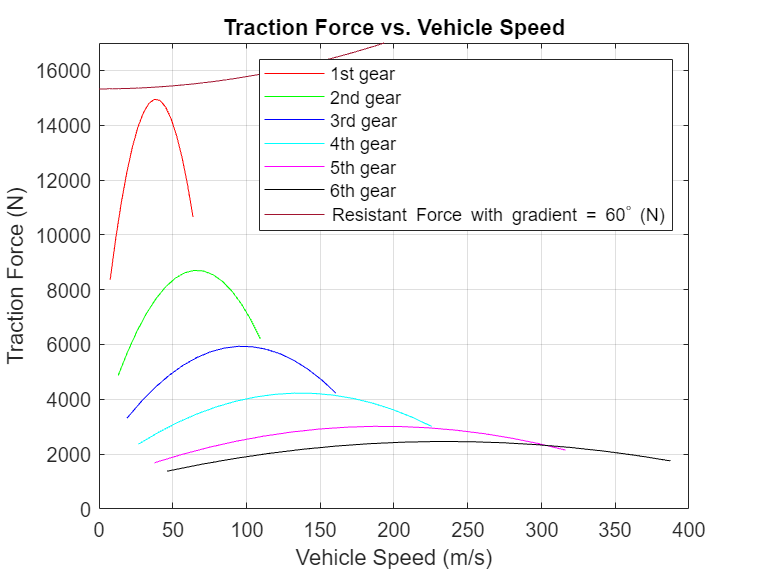

hold on;
% the param of B0 and B1
B0 = weight * g * sin(gradient) + mu_R * weight;
B1 = 0.5 * rho * c_d * A;
% so we can plot the relation with the vehicle speed and the resistance
% force
x_r = 0:0.1:360;
% x_r/3.6 convert kph to m/s
F_r = B0 + B1*(x_r/3.6).^2;

plot(x_r,F_r);
legend_f =sprintf("Resistant Force with gradient = %2.0f", gradient_degree)+"^{\circ} (N)";
legend('1st gear', '2nd gear', '3rd gear', '4th gear', '5th gear', '6th gear', legend_f);
title('Traction Force vs. Vehicle Speed');
xlabel('Vehicle Speed (m/s)');
ylabel('Traction Force (N)');
ylim([0 17000]);

## 5.vehicle dynamics: stable analysis

In order to simulate the  single track model, we need to define other params.

a = 1180*10^-3; % mm->m
b = wheelbase-a;
m1 = 1590; % kg sprung mass
m_f = 102.2; % kg
m_r = 115; % kg
Izz = 2687.1; % kg-m^2 yaw inertia

% the params below is used to linearlize the model
slip_angle_min = 0; % degree
slip_angle_max = 4; % degree


### params lateral force-slip angle

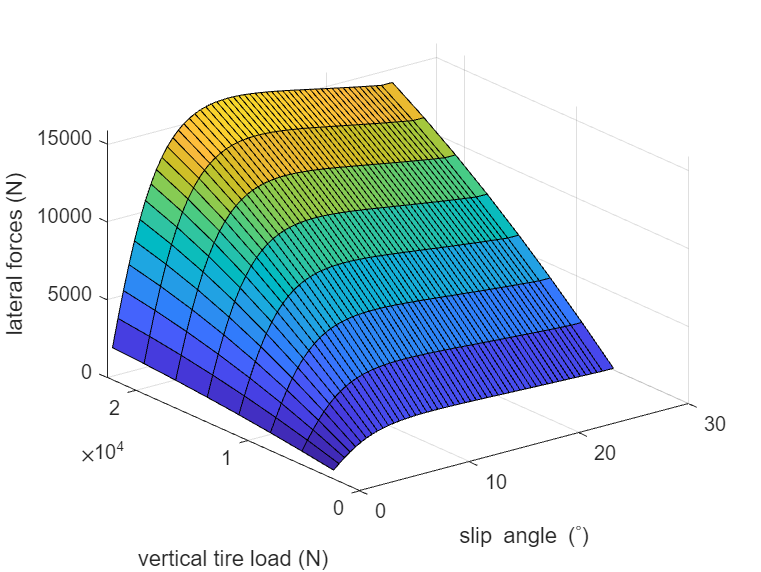

slip_angle_table = readtable('lateral_force_slip_angle.csv');
slip_angle_degrees = slip_angle_table{2:end, 1}';
vertical_tire_loads = slip_angle_table{1,2:end};
lateral_forces = slip_angle_table{2:end,2:end};

% plot the data from carsim
[x,y] = meshgrid(slip_angle_degrees,vertical_tire_loads);
z = lateral_forces';
figure('Color','w');
surf(x,y,z);
xlabel('slip angle (^{\circ})');
ylabel('vertical tire load (N)');
zlabel('lateral forces (N)');
hold off;

## 6.calculate the corresponding lateral forces

In this model, we think the C_a of different tire is different because the vertical load of it is different too which will make the model more precise.

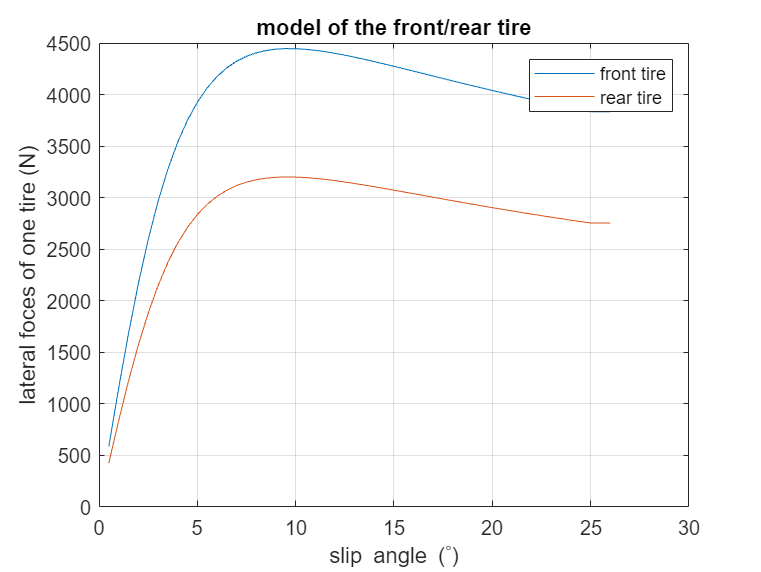

% calculate the vertical load of each tire
front_tire_vertical_load = 0.5*(m1/(a+b)*b + m_f)*g;
rear_tire_vertical_load = 0.5*(m1/(a+b)*a + m_r)*g;

[xx, yy] = meshgrid(slip_angle_degrees,[front_tire_vertical_load,rear_tire_vertical_load]);
% use insert point method
zz = interp2(x,y,z,xx,yy,'spline');
f_vertical_front = zz(1,:);
f_vertical_rear = zz(2,:); 

% plot
figure('Color','w');
plot(slip_angle_degrees,f_vertical_front);
hold on;
grid on;
title("model of the front/rear tire");
plot(slip_angle_degrees,f_vertical_rear);
legend('front tire', 'rear tire');
xlabel('slip angle (^{\circ})');
ylabel('lateral foces of one tire (N)');
hold off;

### linearlize

In the class we used the linearlized model, so we need to linearlize the model the range of the slip angle is [0, 4];

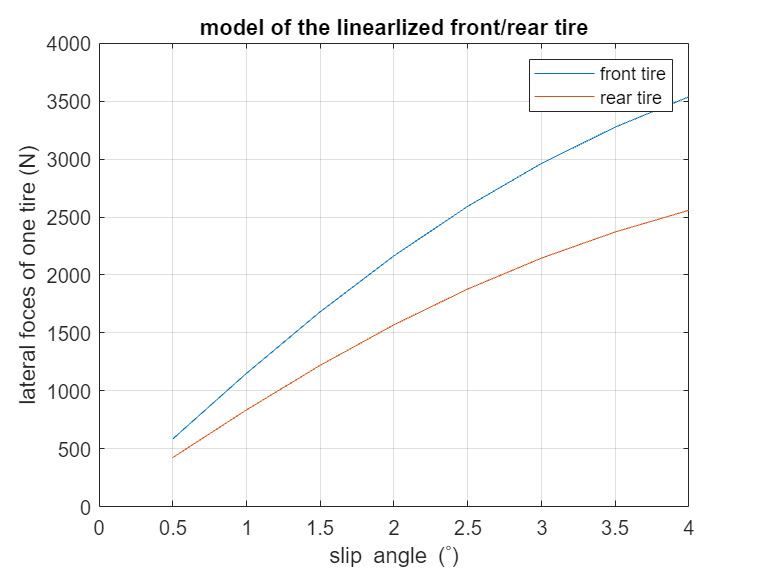

linear_slip_angle = slip_angle_degrees(slip_angle_degrees>=0 & slip_angle_degrees<=4);
linear_vertical_front = f_vertical_front(slip_angle_degrees>=0 & slip_angle_degrees<=4);
linear_vertical_rear = f_vertical_rear(slip_angle_degrees>=0 & slip_angle_degrees<=4);

% plot the reranged part to be linearlized
% plot
figure('Color','w');
plot(linear_slip_angle,linear_vertical_front);
hold on;
grid on;
title("model of the linearlized front/rear tire");
plot(linear_slip_angle,linear_vertical_rear);
legend('front tire', 'rear tire');
xlabel('slip angle (^{\circ})');
ylabel('lateral foces of one tire (N)');
xlim([0 4])
hold off;

then we have to calculate the slop of the front/rear tire

% calculate the slope
fun = @(params, x) params(1) * x; % y = kx
initialParams = 800;

% use least squares method to calculate the slope
params_front = lsqcurvefit(fun, initialParams, linear_slip_angle, linear_vertical_front);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


C_af = 2*params_front(1)*180/pi % rad->degree

C_af = 1.1073e+05


params_rear = lsqcurvefit(fun, initialParams, linear_slip_angle, linear_vertical_rear);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


C_ar = 2*params_rear(1)*180/pi

C_ar = 8.0188e+04


k_us = 1/g*(b*front_tire_vertical_load/wheelbase/C_af - a*rear_tire_vertical_load/wheelbase/C_ar)

k_us = 9.8846e-04

so we can get the dynamic model of the vehicle

v = 35/3.6; % the velocity of the car km/hr -> m/s

% construct the state space
A_dynamic_matrix = -[(C_af+C_ar)/weight/v (a*C_af - b*C_ar)/weight/v + v; (a*C_af - b*C_ar)/v/Izz (a^2*C_af + b^2*C_ar)/v/Izz];
B_dynamic_matrix = [C_af/weight; a*C_af/Izz];

calculate the acceleration time

I_e = 0.3

I_e = 0.3000

m_dynamic_1 = weight + beta_1^2*beta_dif^2/(R_tire^2)*I_e;
C1 = p*beta_1*beta_dif/R_tire;
m_dynamic_2 = weight + beta_2^2*beta_dif^2/(R_tire^2)*I_e;
C2 = p*beta_2*beta_dif/R_tire;

fun1 = @(u) m_dynamic_1./(C1(1).*u.*u+C1(2).*u+C1(3));
fun2 = @(u) m_dynamic_2./(C2(1).*u.*u+C2(2).*u+C2(3));

t1 = integral(fun1, 0, 18.09)

t1 = 8.2814

t2 = integral(fun1, 18.09, 100/3.6)

t2 = 4.3654